data = load("task_data_tables.mat")

data = struct with fields:
    participant: [1×5 struct]


for i=1:length(data.participant)
    ml_ctrl_data_tbl = data.participant(i).ml_ctrl_ttbl;
    cl_ctrl_data_tbl = data.participant(i).cl_ctrl_ttbl;
    hl_ctrl_data_tbl = data.participant(i).hl_ctrl_ttbl;
    ml_expl_data_tbl = data.participant(i).ml_expl_ttbl;
    cl_expl_data_tbl = data.participant(i).cl_expl_ttbl;
    hl_expl_data_tbl = data.participant(i).hl_expl_ttbl;

    participant(i).ml_ctrl_rmse_tbl = make_task_rmse_table(ml_ctrl_data_tbl);
    participant(i).cl_ctrl_rmse_tbl = make_task_rmse_table(cl_ctrl_data_tbl);
    participant(i).hl_ctrl_rmse_tbl = make_task_rmse_table(hl_ctrl_data_tbl);
    participant(i).ml_expl_rmse_tbl = make_task_rmse_table(ml_expl_data_tbl);
    participant(i).cl_expl_rmse_tbl = make_task_rmse_table(cl_expl_data_tbl);
    participant(i).hl_expl_rmse_tbl = make_task_rmse_table(hl_expl_data_tbl);
end

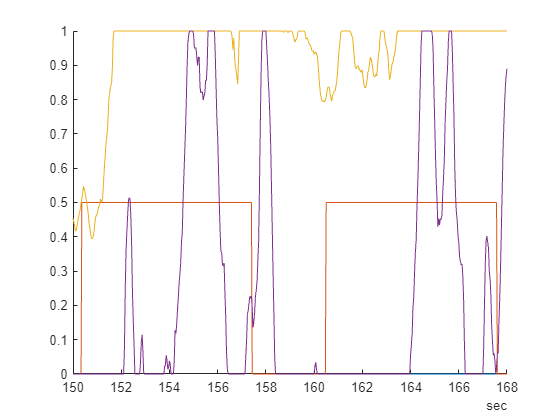

figure
fig_tbl = data.participant(4).hl_expl_ttbl;
hold on
plot(fig_tbl.Time, fig_tbl.("Kinematics (Des)"))
plot(fig_tbl.Time, fig_tbl.("Kinematics (Pred)"))
hold off
box off
xlim([duration([0, 0, 150]) duration([0, 0, 168])])

unique(fig_tbl.("Kinematics (Des)"))

ans =          0
    0.5000


min(unique(fig_tbl.("Kinematics (Pred)")))

ans = 0

trial_window = fig_tbl(and(fig_tbl.Trial==("Trial " + 1), fig_tbl.Gesture=="Power"),:)

trial_window = 212×6 timetable
       Time       Kinematics (Des)     Features      Kinematics (Pred)     Gesture      Trial               Task         
    __________    ________________    ___________    __________________    _______    _________    ______________________

    150.37 sec       0.5    0.5       1×32 double    0.51071          0    "Power"    "Trial 1"    "Human (Experimental)"
    150.4 sec        0.5    0.5       1×32 double    0.52785          0    "Power"    "Trial 1"    "Human (Experimental)"
    150.43 sec       0.5    0.5       1×32 double      0.547          0    "Power"    "Trial 1"    "Human (Experimental)"
    150.47 sec       0.5    0.5       1×32 double   

trial_rmse = rmse(trial_window.("Kinematics (Des)"),trial_window.("Kinematics (Pred)"))

trial_rmse =     0.4527    0.4402


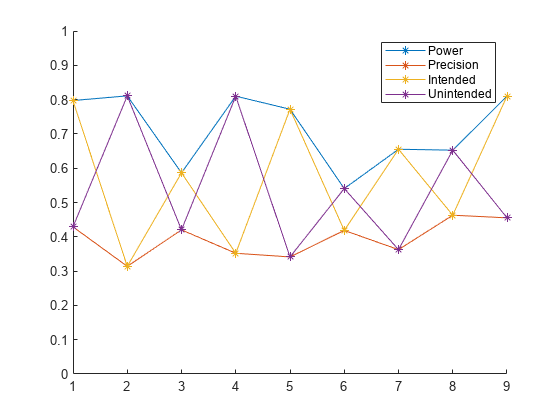

rmse_tbl = participant(4).hl_expl_rmse_tbl;
figure
hold on
plot(rmse_tbl.DOF, '*-')
plot(rmse_tbl.INT, '*-')
hold off
legend(["Power", "Precision", "Intended", "Unintended"])
ylim([0 1])
box off

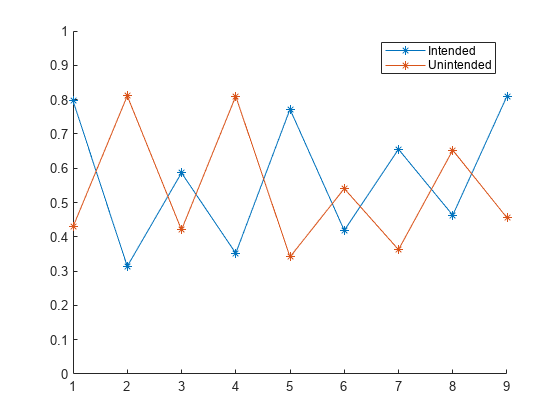


figure
hold on
plot(rmse_tbl.INT, '*-')
hold off
legend(["Intended", "Unintended"])
ylim([0 1])
box off

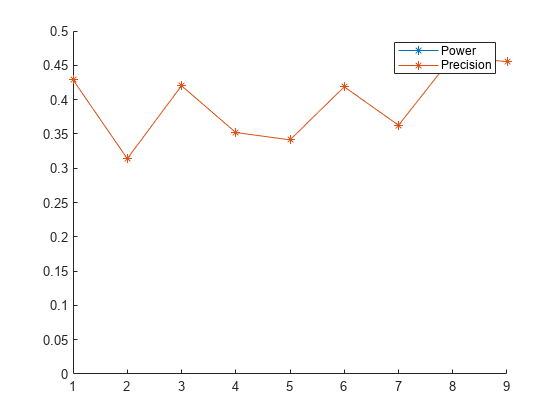

figure
hold on
plot(rmse_tbl.DOF, '*-')
hold off
legend(["Power", "Precision"])
ylim([0 0.5])
box off

function task_rmse_tbl = make_task_rmse_table(task_data_tbl)
task_rmse = [];
for i=1:9
    trial_window = task_data_tbl(task_data_tbl.Trial==("Trial " + i),:);
    trial_rmse = rmse(trial_window.("Kinematics (Des)"),trial_window.("Kinematics (Pred)"));
    task_rmse = [task_rmse; trial_rmse];
end
int_rmse = zeros([9,1]);
int_rmse(1:2:9,1) = task_rmse(1:2:9,1);
int_rmse(2:2:9,1) = task_rmse(2:2:9,2);
xint_rmse = zeros([9,1]);
xint_rmse(1:2:9,1) = task_rmse(1:2:9,2);
xint_rmse(2:2:9,1) = task_rmse(2:2:9,1);
int_rmse = mergevars(array2table([int_rmse, xint_rmse]), ["Var1", "Var2"], "NewVariableName", "INT");
dof_rmse = mergevars(array2table([task_rmse(:,1), task_rmse(:,2)]), ["Var1", "Var2"], "NewVariableName", "DOF");
task_rmse_tbl = [int_rmse, dof_rmse];
end